# **Linear Regression Using Genetic Algorithm**

**Clear existing variables and confirm that your Current Folder is set correctly**

clear;
clc;
dir;

.                               computeCostMulti.m              geneticAlgorithm.m              
..                              crossover.m                     initializePopulation.m          
CAR_DETAILS_FROM_CAR_DEKHO.csv  data.csv                        mutation.m                      
Car_details_v3.csv              elitismSelection.m              selection.m                     
CostFunction.m                  ex1.mlx                         
LinearRegression_UsingGA.mlx    ex1_companion.mlx               
car_data.csv                    ex1data2.txt                    



**Load the data set into a table**

uiimport("car_data.csv");

summary(data);

Variables:

    Car_Name: 301×1 categorical

        Values:

            800                              1   
            Activa 3g                        2   
            Activa 4g                        1   
            Bajaj  ct 100                    1   
            Bajaj Avenger 150                1   
            Bajaj Avenger 150 street         1   
            Bajaj Avenger 220                3   
            Bajaj Avenger 220 dtsi           2   
            Bajaj Avenger Street 220         1   
            Bajaj Discover 100               1   
            Bajaj Discover 125               2   
            Bajaj Dominar 400                1   
            Bajaj Pulsar  NS 200             1   
            Bajaj Pulsar 135 LS              1   
            Bajaj Pulsar 150                 4   
            Bajaj Pulsar 220 F               2   
            Bajaj Pulsar NS 200              3   
            Bajaj Pulsar RS200               1   
            Hero  CBZ

methods(data);

Methods for class table:

addprop       horzcat       ismember      movevars      renamevars    setxor        summary       unique        
addvars       inner2outer   isprop        ndims         rmprop        size          table         unstack       
cat           innerjoin     issortedrows  numel         rowfun        sortrows      tail          varfun        
convertvars   intersect     join          outerjoin     rows2vars     splitvars     topkrows      vertcat       
head          isempty       mergevars     removevars    setdiff       stack         union         



**Check for missing value**

check = ismissing(data);
MissingValue = sum(check, 'all')

MissingValue = 0

**Data Preprocessing**

Age = 2020 - data.Year;
data = addvars(data, Age);
data = removevars(data, 'Year')

data = 301×9 table
      Car_Name       Selling_Price    Present_Price    Kms_Driven    Fuel_Type    Seller_Type    Transmission    Owner    Age
    _____________    _____________    _____________    __________    _________    ___________    ____________    _____    ___

    ritz                 3.35              5.59          27000        Petrol        Dealer        Manual           0       6 
    sx4                  4.75              9.54          43000        Diesel        Dealer        Manual           0       7 
    ciaz                 7.25              9.85           6900        Petrol        Dealer        Manual           0       3 
    wagon r              2.85              4

**Exploratory Data Analysis (EDA)**

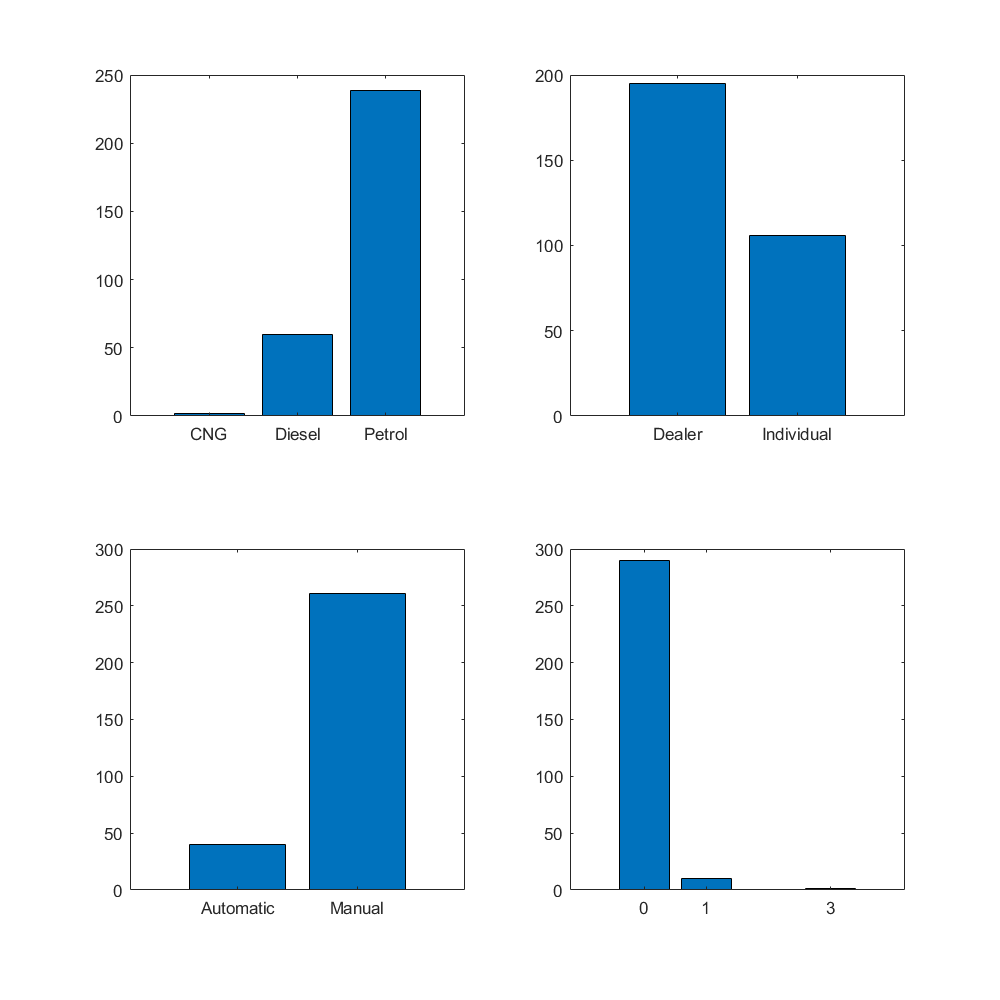

fig = figure;
fig.Position(3:4) = [820 820];

subplot(2, 2, 1);
[gc1, gr1] = groupcounts(data.Fuel_Type);
bar(gr1, gc1);

subplot(2, 2, 2);
[gc2, gr2] = groupcounts(data.Seller_Type);
bar(gr2, gc2);

subplot(2, 2, 3);
[gc3, gr3] = groupcounts(data.Transmission);
bar(gr3, gc3);

subplot(2, 2, 4);
[gc4, gr4] = groupcounts(data.Owner);
bar(gr4, gc4);

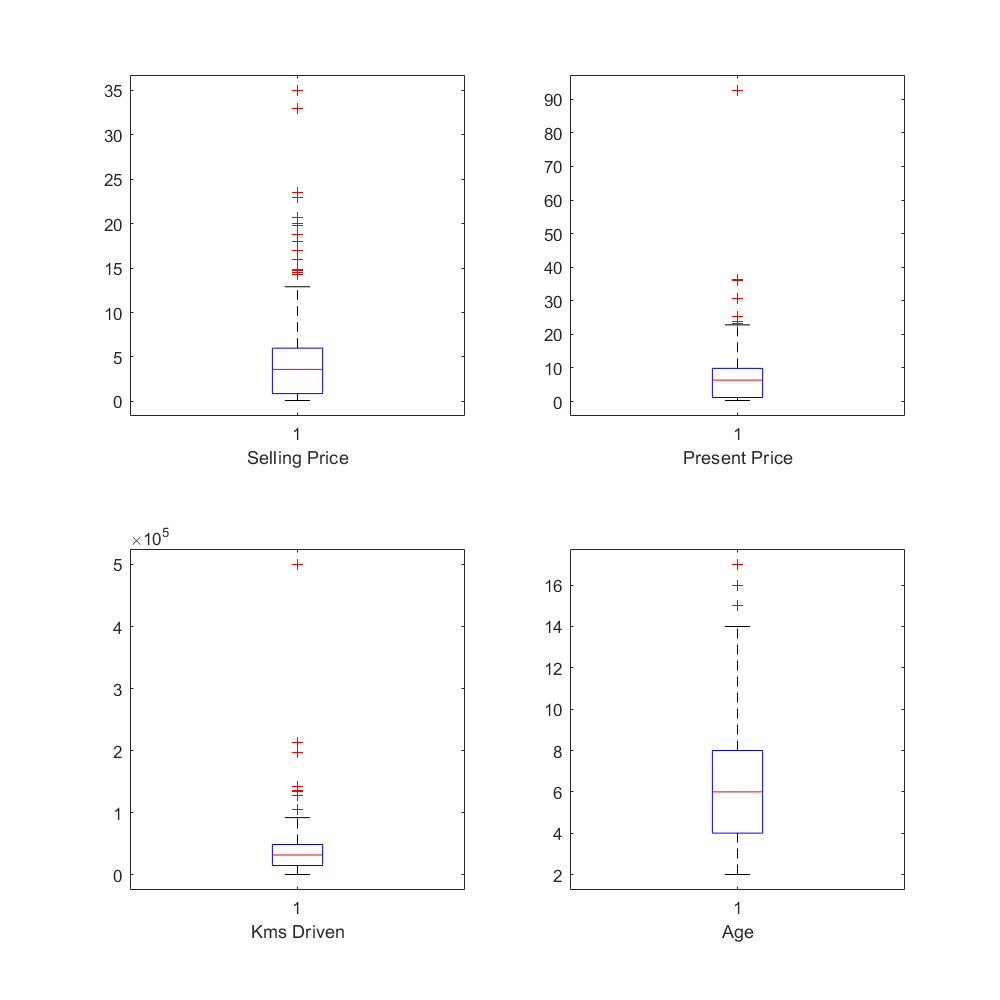

fig = figure;
fig.Position(3:4) = [820 820];

subplot(2, 2, 1);
boxplot(data.Selling_Price);
xlabel('Selling Price');

subplot(2, 2, 2);
boxplot(data.Present_Price);
xlabel('Present Price');

subplot(2, 2, 3);
boxplot(data.Kms_Driven);
xlabel('Kms Driven');

subplot(2, 2, 4);
boxplot(data.Age);
xlabel('Age');

data(data.Present_Price > quantile(data.Present_Price, 0.99), :)

ans = 2×9 table
      Car_Name      Selling_Price    Present_Price    Kms_Driven    Fuel_Type    Seller_Type    Transmission    Owner    Age
    ____________    _____________    _____________    __________    _________    ___________    ____________    _____    ___

    fortuner             33              36.23           6000        Diesel        Dealer        Automatic        0       3 
    land cruiser         35               92.6          78000        Diesel        Dealer        Manual           0      10 


data(data.Selling_Price > quantile(data.Selling_Price, 0.99), :)

ans = 3×9 table
      Car_Name      Selling_Price    Present_Price    Kms_Driven    Fuel_Type    Seller_Type    Transmission    Owner    Age
    ____________    _____________    _____________    __________    _________    ___________    ____________    _____    ___

    fortuner            23.5             35.96          47000        Diesel        Dealer        Automatic        0       5 
    fortuner              33             36.23           6000        Diesel        Dealer        Automatic        0       3 
    land cruiser          35              92.6          78000        Diesel        Dealer        Manual           0      10 


data(data.Kms_Driven > quantile(data.Kms_Driven, 0.99), :)

ans = 3×9 table
      Car_Name       Selling_Price    Present_Price    Kms_Driven    Fuel_Type    Seller_Type    Transmission    Owner    Age
    _____________    _____________    _____________    __________    _________    ___________    ____________    _____    ___

    innova               3.49             13.46        1.9718e+05     Diesel      Dealer          Manual           0      15 
    Honda Karizma        0.31              1.05          2.13e+05     Petrol      Individual      Manual           0      10 
    Activa 3g            0.17              0.52             5e+05     Petrol      Individual      Automatic        0      12 


**Bivariate/Multi-variate Analysis**

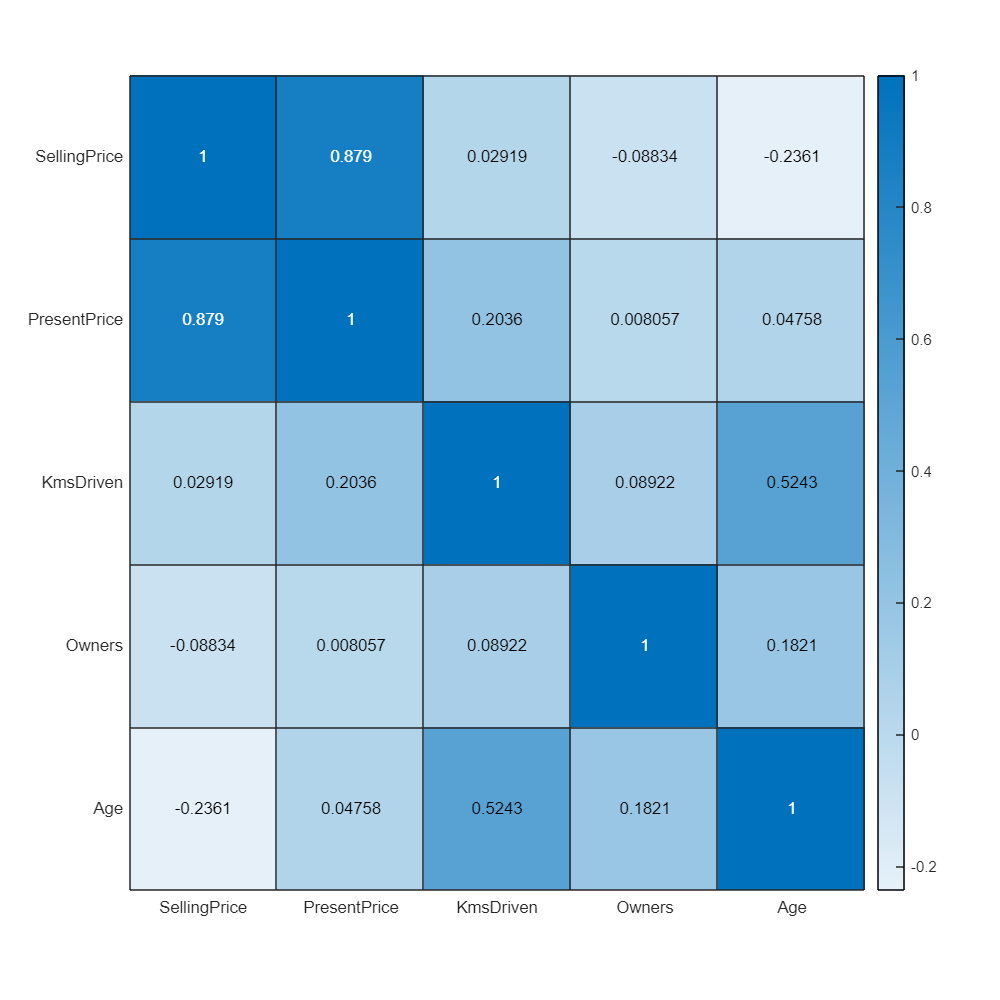

corrMatrix = corr([data.Selling_Price data.Present_Price data.Kms_Driven data.Owner data.Age]);
fig = figure;
fig.Position(3:4) = [820 820];
variables = {'SellingPrice', 'PresentPrice', 'KmsDriven', 'Owners', 'Age'};
heatmap(variables, variables, corrMatrix)

**Data preparation**

% remove unnecessary variables
data = removevars(data, 'Car_Name');
% One hot encoding
tbl = removevars(data, {'Selling_Price', 'Present_Price', 'Kms_Driven', 'Owner', 'Age'});
encData = table();
for i = 1:3
    encData = [encData onehotencode(tbl(:,i))];
end
encData = removevars(encData, {'CNG', 'Dealer', 'Automatic'});
% Separate target and variable, and its features
y = data.Selling_Price;
% Remove encrypted and target variables
data = removevars(data, {'Fuel_Type', 'Seller_Type', 'Transmission', 'Selling_Price'});

%convert table to matrix
data = table2array(data);
encData = table2array(encData);
%normalize feature
data = normalize(data);
data = [data encData];

**Train/Test Split**

data = [ones(size(data, 1), 1) data];
X_train = data(1:240, :);
X_test = data(241:301, :);
y_train = y(1:240);
y_test = y(241:301);

**Model Creation/Evaluation**

% Genetic Algorithm

k = 400;
epoch = 400;
[best, best_cost, minCostOverEpoch] = geneticAlgorithm(X_train, y_train, epoch, k)

best =     1.1831    3.5965   -0.1360   -0.1693   -1.0652    6.7758    4.8126   -0.9832   -1.4254


best_cost = 3.7981

minCostOverEpoch =    25.1252
   43.2349
   42.2095
   42.0781
   39.0596
   26.7276
   31.5120
   41.9829
   21.0749
   31.0553


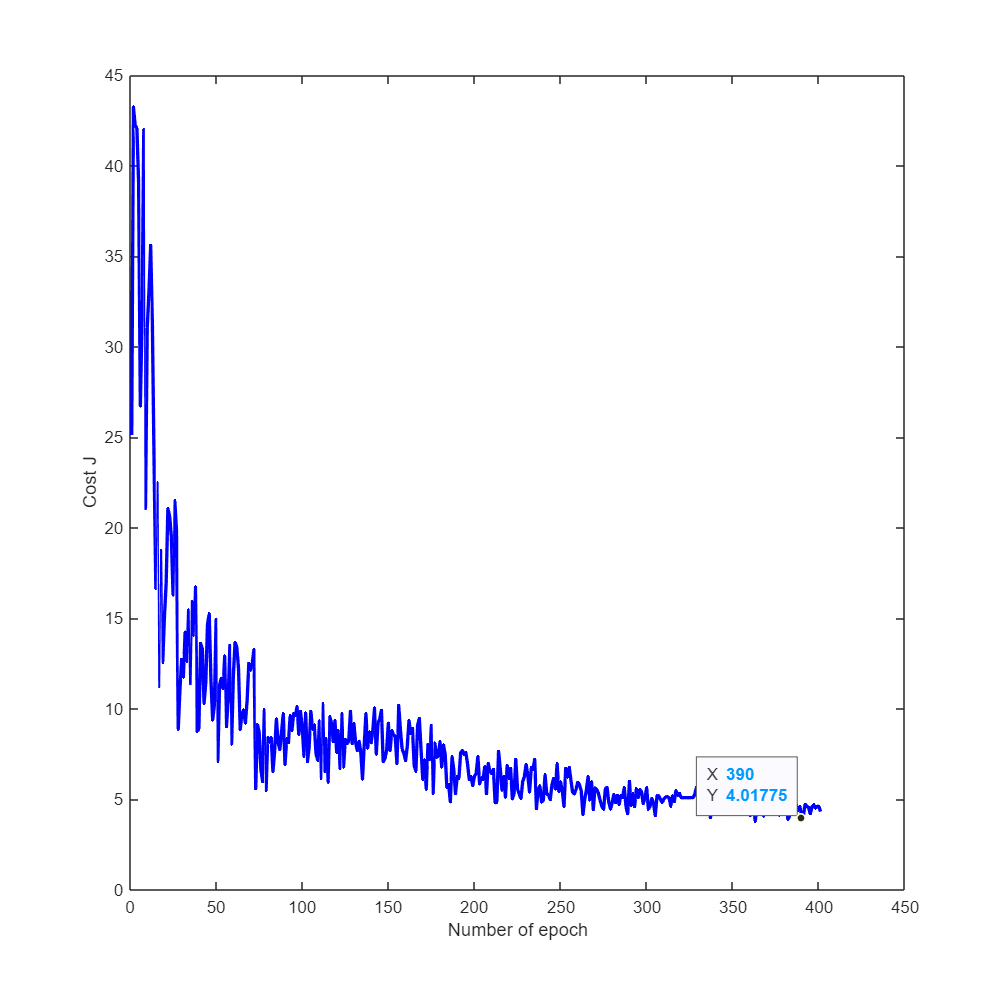

fig = figure;
fig.Position(3:4) = [820 820];
xaxis = 1:(epoch + 1);
plot(xaxis, minCostOverEpoch, '-b', 'LineWidth', 2)
xlabel('Number of epoch');
ylabel('Cost J');

**Compare with a pre-built linear model in matlab (using *****fitlm*****)**

uiimport("data.csv");

linMdl = fitlm(data1);
theta = linMdl.Coefficients.Estimate

theta =     5.4555
    3.7076
   -0.2768
   -0.1846
   -1.0461
    2.5456
    0.4404
   -0.9919
   -1.5988


minCost = costFunction(X_train, y_train, theta')

minCost = 3.5645